# Locally Weighted Scatterplot Smoothing

A program which is developed based on lowess approach for smoothing rate-normalized pressure (RNP) data.

Author: Munthe, Felix A.

Created on Monday, 30 October 2103

## Import Data

### True RNP Data

clear; clc; clf;
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
true_RNP = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\true_RNP.txt", opts)

true_RNP = 1150×2 table
       t          RNP    
    _______    __________

       0.25    1.3616e+06
    0.33041    1.9565e+06
     0.4862    2.6089e+06
    0.79777    3.4782e+06
     1.4209    4.6953e+06
     2.6672    6.4232e+06
     5.0773    8.8236e+06
     9.8974    1.2258e+07
     19.198    1.7054e+07
     35.645    2.3347e+07
      66.06    3.1893e+07
     124.99    4.3906e+07
     188.99    5.4925e+07
     252.99    6.4572e+07
     316.99    7.3193e+07
     380.99     8.103e+07


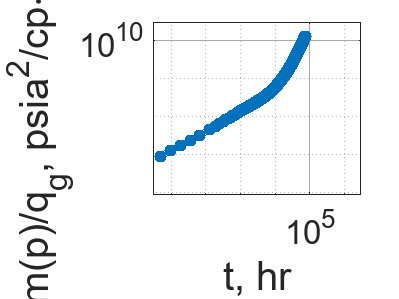


% Plot
loglog(true_RNP.t, true_RNP.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("True RNP Data", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

### Noisy RNP Data Set 210

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
noisy_RNP_210 = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\Noisy RNP Model\All\75%\noisy_data_10.txt", opts)

noisy_RNP_210 = 1150×2 table
       t          RNP    
    _______    __________

       0.25    1.4958e+08
    0.33041    1.2425e+08
     0.4862    9.5788e+07
    0.79777    2.2095e+08
     1.4209    6.5124e+07
     2.6672    2.2975e+08
     5.0773    1.2763e+08
     9.8974    2.5182e+08
     19.198    8.4737e+07
     35.645    1.0451e+08
      66.06    1.9288e+08
     124.99    4.3906e+07
     188.99    1.1644e+08
     252.99    6.4572e+07
     316.99    1.7121e+08
     380.99     8.103e+07


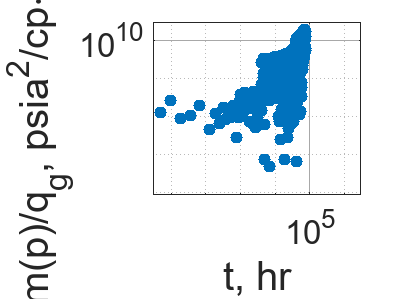


% Plot
loglog(noisy_RNP_210.t, noisy_RNP_210.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("Noisy RNP Data Set 210", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

## Smoothing

### Noisy RNP Data 210

logRNP_210 = log(noisy_RNP_210.RNP);

#### Window: 3

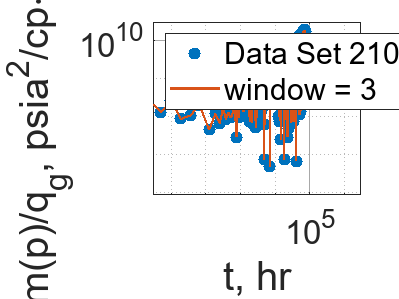

% Plot
loglog(noisy_RNP_210.t, noisy_RNP_210.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 210");
% title("Noisy RNP Data Set 210", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_210_31 = smooth(logRNP_210, 3, "lowess");
smoothedRNP_210_31 = exp(smoothedLogRNP_210_31);
residual_210_31 = (true_RNP.RNP - smoothedRNP_210_31) ./ (0.3413 .* true_RNP.RNP);
sse_210_31 = sum(residual_210_31 .^ 2);
loglog(noisy_RNP_210.t, smoothedRNP_210_31, "-", "LineWidth", 1.3, "DisplayName", "window = 3");
legend("Location", "northwest");
hold off;

### Window: 5

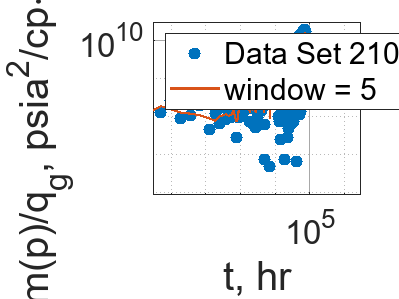

% Plot
loglog(noisy_RNP_210.t, noisy_RNP_210.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 210");
% title("Noisy RNP Data Set 210", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_210_51 = smooth(logRNP_210, 5, "lowess");
smoothedRNP_210_51 = exp(smoothedLogRNP_210_51);
residual_210_51 = (true_RNP.RNP - smoothedRNP_210_51) ./ (0.3413 .* true_RNP.RNP);
sse_210_51 = sum(residual_210_51 .^ 2);
loglog(noisy_RNP_210.t, smoothedRNP_210_51, "-", "LineWidth", 1.3, "DisplayName", "window = 5");
legend("Location", "northwest");
hold off;

#### Window: 7

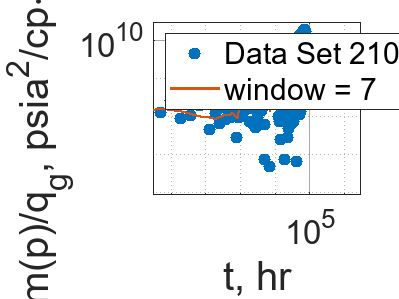

% Plot
loglog(noisy_RNP_210.t, noisy_RNP_210.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 210");
% title("Noisy RNP Data Set 210", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_210_71 = smooth(logRNP_210, 7, "lowess");
smoothedRNP_210_71 = exp(smoothedLogRNP_210_71);
residual_210_71 = (true_RNP.RNP - smoothedRNP_210_71) ./ (0.3413 .* true_RNP.RNP);
sse_210_71 = sum(residual_210_71 .^ 2);
loglog(noisy_RNP_210.t, smoothedRNP_210_71, "-", "LineWidth", 1.3, "DisplayName", "window = 7");
legend("Location", "northwest");
hold off;

#### Window: 9

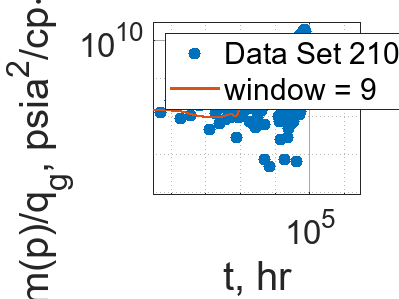

% Plot
loglog(noisy_RNP_210.t, noisy_RNP_210.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 210");
% title("Noisy RNP Data Set 210", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_210_91 = smooth(logRNP_210, 9, "lowess");
smoothedRNP_210_91 = exp(smoothedLogRNP_210_91);
residual_210_91 = (true_RNP.RNP - smoothedRNP_210_91) ./ (0.3413 .* true_RNP.RNP);
sse_210_91 = sum(residual_210_91 .^ 2);
loglog(noisy_RNP_210.t, smoothedRNP_210_91, "-", "LineWidth", 1.3, "DisplayName", "window = 9");
legend("Location", "northwest");
hold off;

#### Window: 11

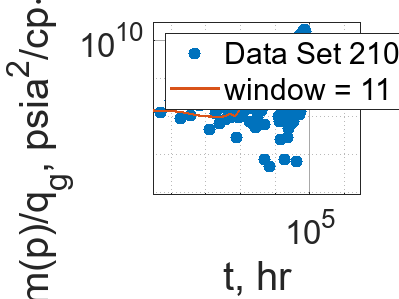

% Plot
loglog(noisy_RNP_210.t, noisy_RNP_210.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 210");
% title("Noisy RNP Data Set 210", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_210_111 = smooth(logRNP_210, 11, "lowess");
smoothedRNP_210_111 = exp(smoothedLogRNP_210_111);
residual_210_111 = (true_RNP.RNP - smoothedRNP_210_111) ./ (0.3413 .* true_RNP.RNP);
sse_210_111 = sum(residual_210_111 .^ 2);
loglog(noisy_RNP_210.t, smoothedRNP_210_111, "-", "LineWidth", 1.3, "DisplayName", "window = 11");
legend("Location", "northwest");
hold off;

#### Window: 13

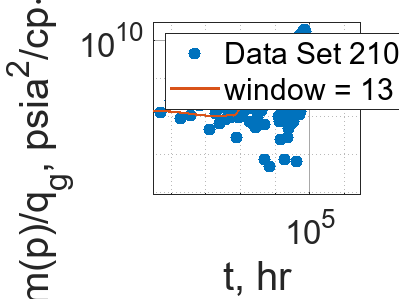

% Plot
loglog(noisy_RNP_210.t, noisy_RNP_210.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 210");
% title("Noisy RNP Data Set 210", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_210_131 = smooth(logRNP_210, 13, "lowess");
smoothedRNP_210_131 = exp(smoothedLogRNP_210_131);
residual_210_131 = (true_RNP.RNP - smoothedRNP_210_131) ./ (0.3413 .* true_RNP.RNP);
sse_210_131 = sum(residual_210_131 .^ 2);
loglog(noisy_RNP_210.t, smoothedRNP_210_131, "-", "LineWidth", 1.3, "DisplayName", "window = 13");
legend("Location", "northwest");
hold off;

#### Window: 15

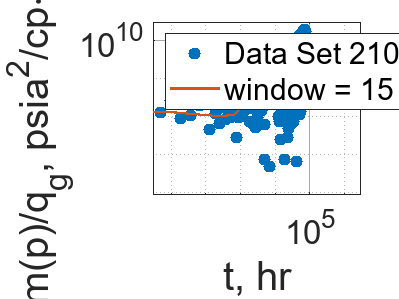

% Plot
loglog(noisy_RNP_210.t, noisy_RNP_210.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 210");
% title("Noisy RNP Data Set 210", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_210_151 = smooth(logRNP_210, 15, "lowess");
smoothedRNP_210_151 = exp(smoothedLogRNP_210_151);
residual_210_151 = (true_RNP.RNP - smoothedRNP_210_151) ./ (0.3413 .* true_RNP.RNP);
sse_210_151 = sum(residual_210_151 .^ 2);
loglog(noisy_RNP_210.t, smoothedRNP_210_151, "-", "LineWidth", 1.3, "DisplayName", "window = 15");
legend("Location", "northwest");
hold off;

#### Window: 17

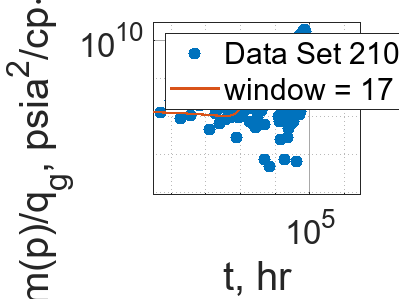

% Plot
loglog(noisy_RNP_210.t, noisy_RNP_210.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 210");
% title("Noisy RNP Data Set 210", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_210_171 = smooth(logRNP_210, 17, "lowess");
smoothedRNP_210_171 = exp(smoothedLogRNP_210_171);
residual_210_171 = (true_RNP.RNP - smoothedRNP_210_171) ./ (0.3413 .* true_RNP.RNP);
sse_210_171 = sum(residual_210_171 .^ 2);
loglog(noisy_RNP_210.t, smoothedRNP_210_171, "-", "LineWidth", 1.3, "DisplayName", "window = 17");
legend("Location", "northwest");
hold off;

#### Window: 19

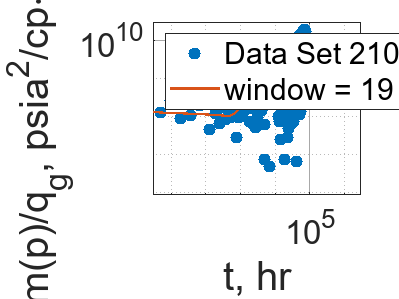

% Plot
loglog(noisy_RNP_210.t, noisy_RNP_210.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 210");
% title("Noisy RNP Data Set 210", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_210_210 = smooth(logRNP_210, 19, "lowess");
smoothedRNP_210_210 = exp(smoothedLogRNP_210_210);
residual_210_210 = (true_RNP.RNP - smoothedRNP_210_210) ./ (0.3413 .* true_RNP.RNP);
sse_210_210 = sum(residual_210_210 .^ 2);
loglog(noisy_RNP_210.t, smoothedRNP_210_210, "-", "LineWidth", 1.3, "DisplayName", "window = 19");
legend("Location", "northwest");
hold off;